# MAE 182 Final Project Master Live Script

Miles Puchner

MAE 182

Professor Rosengren

21 March 2024

## B.O.P.P.A. Master Live Script

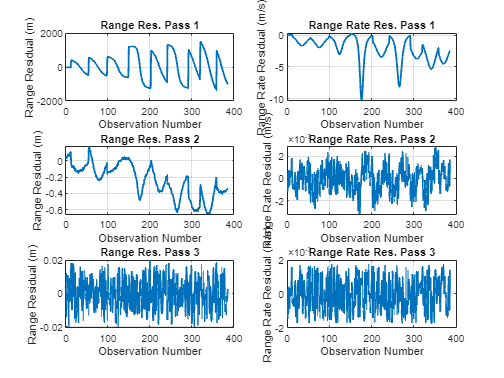

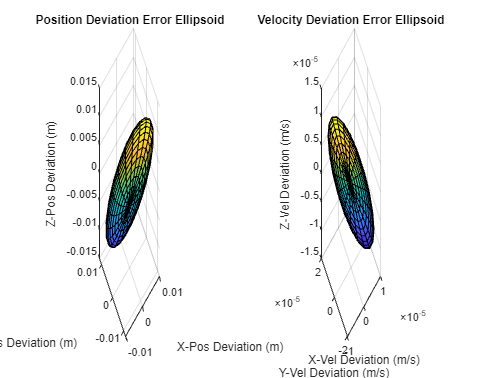

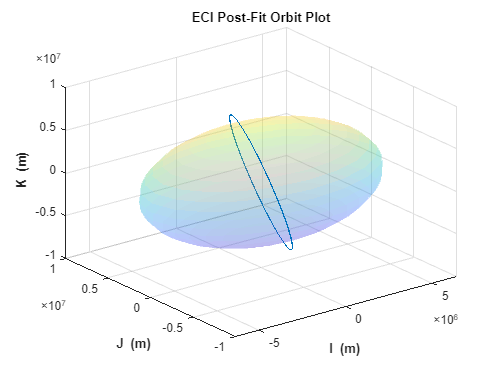

RMS = 1.0e+02 *

   7.327483054387566   0.003195700385817   0.000097248991576
   0.029001652697236   0.000011996972846   0.000009979242553


x0_hat = 1.0e+07 *

  -0.000000003630222   0.000000032672595  -0.000000000000000   0.000000029042373
  -0.000000027410718  -0.000000014806348  -0.000000000000048  -0.000000042217114
  -0.000000018087494  -0.000000008099461   0.000000000000044  -0.000000026186912
   0.000000004093496  -0.000000000031715  -0.000000000000000   0.000000004061781
   0.000000003274840  -0.000000000003922   0.000000000000000   0.000000003270917
  -0.000000001475304   0.000000000033803   0.000000000000000  -0.000000001441501
  -0.946343507421743  -3.330614715416829  -0.000001638960318  -4.276959861798891
  -0.000000000000066   0.000000000000003  -0.000000000000000  -0.000000000000063
   0.000000014756346   0.000000004114623  -0.000000000000029   0.000000018870940
   0.000000000000186  -0.000000000000187   0.000000000000000  -0.000000000000001


clear
clc
warning off
close all
format long
tic
%----------------------------------------------------------------%
%                   Dynamic/Reference Constants                  %
%----------------------------------------------------------------%

    % Planetary constants
    const.mu = 3.986004415e14; % [m^3/s^2]
    const.J2 = 1.082626925638815e-3;
    const.Re = 6378136.3; % [m]
    const.thetadot = 7.2921158553e-5; % [rad/s]

    % Spacecraft parameters
    const.Cd = 2;
    const.Ar = 3; % [m^2]
    const.m = 970; % [kg]

    % Atmospheric Drag reference values
    const.r0 = 700000 + const.Re; % [m]
    const.rho0 = 3.614e-13; % [kg/m^3]
    const.H = 88667; % [m]



%----------------------------------------------------------------%
%              Observation Site Coordinates (ECEF)               %
%----------------------------------------------------------------%

    % Define the initial site coordinates in the ECEF frame
          %       X          Y          Z         [m]
    site1 = [ -5127510 ; -3794160 ;     0    ];

    site2 = [  3860910 ;  3238490 ;  3898094 ];

    site3 = [  549505  ; -1380872 ;  6182197 ];

    
    site = [site1, site2, site3];



%----------------------------------------------------------------%
%                Integration & Batch Parameters                  %
%----------------------------------------------------------------%

    % Define the time span for which to integrate the dynamics
    tspan = 0:20:18340; % [s]

    % Define the number of Batch iterations
    n = 3; % (3 iterations recommended)



%----------------------------------------------------------------%
%                  Initial Spacecraft State                      %
%----------------------------------------------------------------%

    % Define the initial satellite position and velocity
        %      X        Y         Z   [m]      Xdot     Ydot       Zdot   [m/s]
    rv0 = [ 757700 ; 5222607 ; 4851500   ;   2213.21 ; 4678.34 ; -5371.3 ];



%----------------------------------------------------------------%
%                  Imported Observation Data                     %
%----------------------------------------------------------------%

    % Read in the observations (see user guide for format)
    obs_data = importdata('exam_obs_data.txt');



%----------------------------------------------------------------%
%           State/Observation Statistical Parameters             %
%----------------------------------------------------------------%

    % Define observation parameters
    x0_bar = zeros(18, 1);

    P0_bar = diag([1e6, 1e6, 1e6, 1e6, 1e6, 1e6, 1e20, 1e6, 1e6, ...
        1e-10, 1e-10, 1e-10, 1e6, 1e6, 1e6, 1e6, 1e6, 1e6]);
    
    sig_rho = 0.01; % [m]
    sig_rhodot = 0.001; % [m/s]
    R = [sig_rho^2,     0; 
            0,     sig_rhodot^2];



%----------------------------------------------------------------%
%                     Main Function Call                         %
%----------------------------------------------------------------%

% Call the batch function to solve the Orbit-Determination problem
[RMS, x0_hat] = boppa( rv0, site, tspan, x0_bar, P0_bar, R, obs_data, n, const )

toc

Elapsed time is 8.287508 seconds.
